# **Training CN-vs-MCIc**

Due to memory (RAM) and computational power limits, instead of converting each MRI in one hundred pictures, in this code we are going to extract 6 slices only for each MRI, to train on 3 folds instead of 20, and not to perform any data augmentation.

### **Code structure:**

**1) Define the network (Transfer Learning from AlexNet)**

**2) Set training parameters**

**3) Load the Dataset:**

- Load .mat files

- Concatenate CN_training, CN_testing, etc... in a single cell array

- Transform the 238 MRI images into 714 (=238*3) 227x227x3 images (~1GB)

**4) Cross Fold Validation (for 2 folds):**

- Find patterns to use for Testing (index==fold) and Training (index!=fold) and split the dataset in Training and Testing for this fold

- Shuffle the trainingImages (and their labels, respectively)

- Train

- Save the trained model

- Validate on TestSet

- Compute Metrics

## **Problem parameters**

clear all
warning off

% Type of problem
problem="CN_vs_MCIc";
%problem="CN_vs_AD";
%problem="MCInc_vs_MCIc";

% Axis
axis="x-axis";
%axis="y-axis";
%axis="z-axis";

% Dataset parameters
nSlices=6; %Number of slices to extract for each MRI
gap=2;  %Gap between slices (=1 means no slices between, =2 means 1 slice between)

%---------------------------------------------------------------
time=datestr(now,"yyyy_mm_dd_HH_MM"); %Save execution time

% where to save current execution outputs
directory="../TrainedModels/"+problem+"/"+axis+"/"+time+"/";
% Create directories if doesn't exist
if ~exist("../TrainedModels", 'dir')
   mkdir("../TrainedModels")
end
if ~exist("../TrainedModels/"+problem, 'dir')
   mkdir("../TrainedModels/"+problem)
end
if ~exist("../TrainedModels/"+problem+"/"+axis, 'dir')
   mkdir("../TrainedModels/"+problem+"/"+axis)
end
mkdir("../TrainedModels/"+problem+"/"+axis+"/"+time)

## **1) Define the Network**

by modifing the last 3 layers of AlexNet

siz=[227 227]; % input size of the CNN (AlexNet)

net = alexnet;
layers=net.Layers;
layers(end-2)=fullyConnectedLayer(2,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20);
layers(end-1)=softmaxLayer;
layers(end)=classificationLayer;

## **2) Set training parameters**

folds=3;

miniBatchSize = 30;
learningRate = 1e-4;
maxEpochs=10;
optimizer='sgdm';

options=trainingOptions(optimizer,...
    "MiniBatchSize",miniBatchSize,...
    "InitialLearnRate",learningRate,...
    'MaxEpochs',maxEpochs,...
    "Verbose",false,...
    "Plots","training-progress");

## **3) Load the Dataset**

**Load CN.mat and MCIc.mat**

**Concatenate CN_training, CN_testing, MCIc_training, MCIc_testing in a single cell array**

% Concatenate all dataset files in a single cell array
load("../Dataset/CN.mat")
load("../Dataset/MCIc.mat")
dataset=cat(1,CN_training,CN_testing,MCIc_training,MCIc_testing);

% Create label array
lengthClass1=(length(CN_training)+length(CN_testing));
lengthClass2=(length(MCIc_training)+length(MCIc_testing));
mriLabel(1:lengthClass1)=1; %Cognitive Normal = 1
mriLabel(lengthClass1:lengthClass1+lengthClass2)=2;

clear CN_training CN_testing MCIc_training MCIc_testing lengthClass1 lengthClass2

**Transform the 238 MRI images into 1428 (=238*6) 227x227x3 images (~1GB)**

Images=[];
label=[]; % labels of classes 
labelID=[]; % labels of ID
tmpTR=1;
for i=1:length(mriLabel)
    % Extract single MRI
    IMG=dataset{i};

    % Transform MRI picture into 3 images 227x227x3
    IMG=mriToCNN(IMG,siz,axis);
    Images(:,:,:,tmpTR:tmpTR+size(IMG,4)-1)=IMG;

    % Return label vector with labels of the new 3 pictures
    class=mriLabel(i);
    label(tmpTR:tmpTR+size(IMG,4)-1)=class;

    % Save single person's ID
    labelID(tmpTR:tmpTR+size(IMG,4)-1)=i;

    tmpTR=tmpTR+size(IMG,4); %Increasing counter by 3

    clear IMG;
end

clear dataset mriLabel class tmpTR

## **4) Cross fold validation (3 fold)**

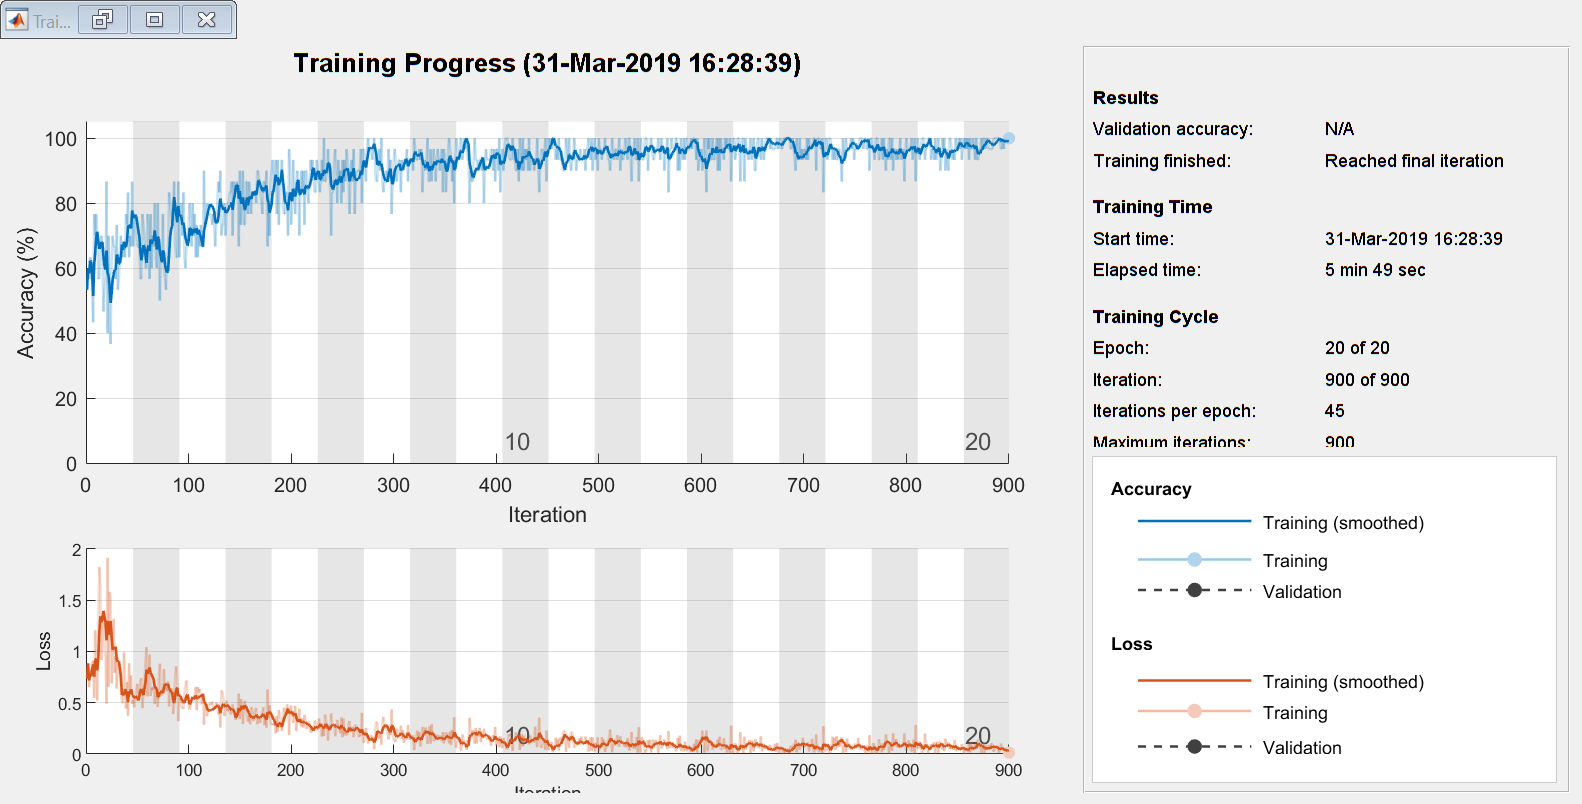

TP = 0

TN = 28

FP = 20

FN = 18

precision = 0

recall = 0

f1 = NaN

specificity = 0.4167

accuracy = 0.4242

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


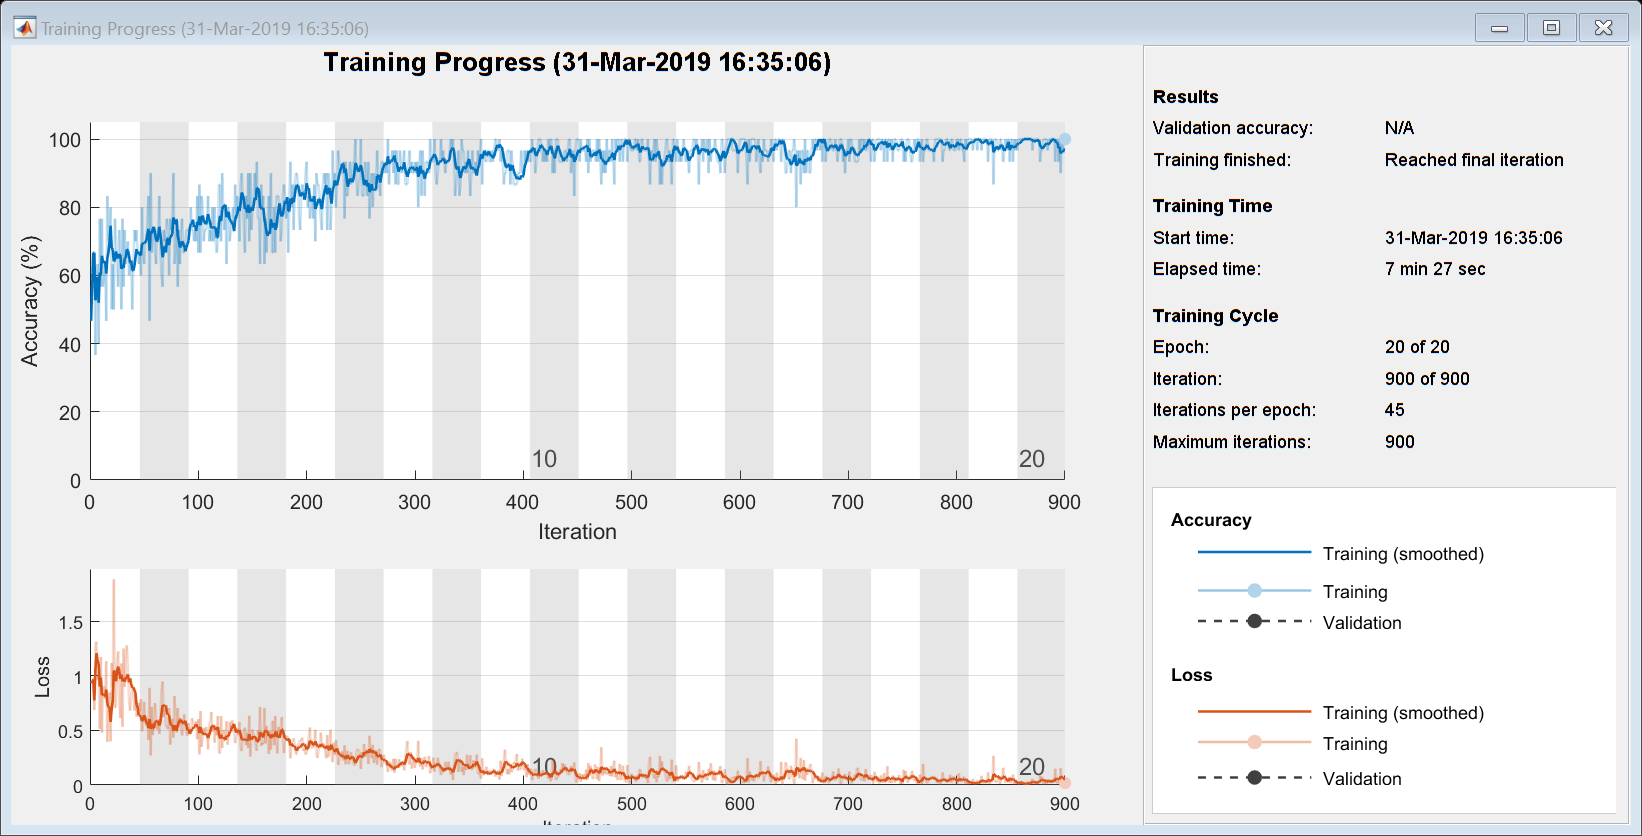

TP =      0     0


TN =     28    43


FP =     20     5


FN =     18    24


precision =      0     0


recall =      0     0


f1 =    NaN   NaN


specificity =     0.4167    0.1042


accuracy =     0.4242    0.5972


ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


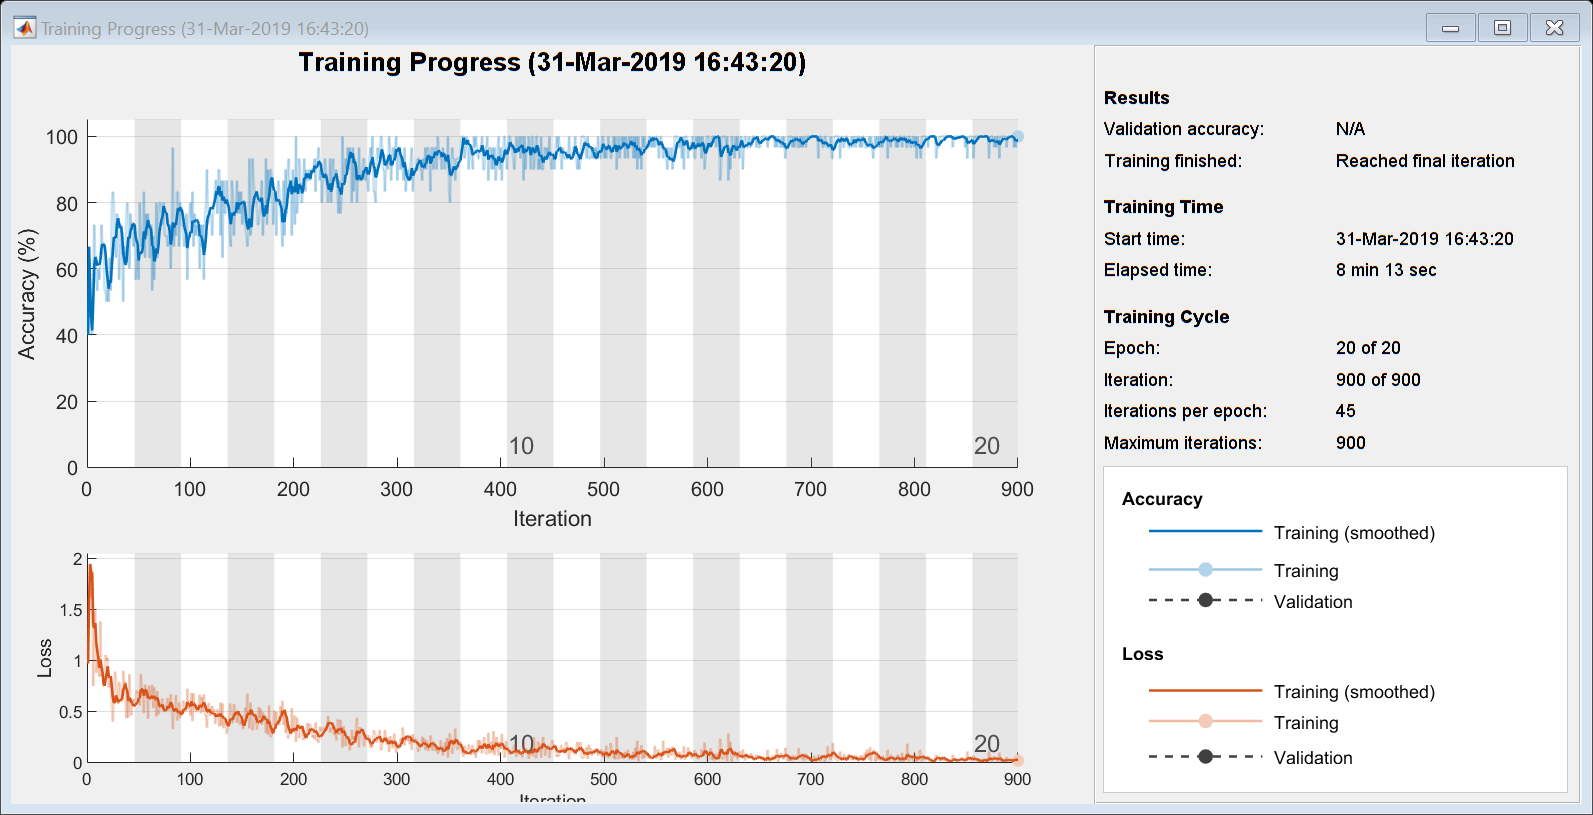

TP =      0     0    10


TN =     28    43    31


FP =     20     5    17


FN =     18    24    14


precision =          0         0    0.3704


recall =          0         0    0.4167


f1 =        NaN       NaN    0.3922


specificity =     0.4167    0.1042    0.3542


accuracy =     0.4242    0.5972    0.5694


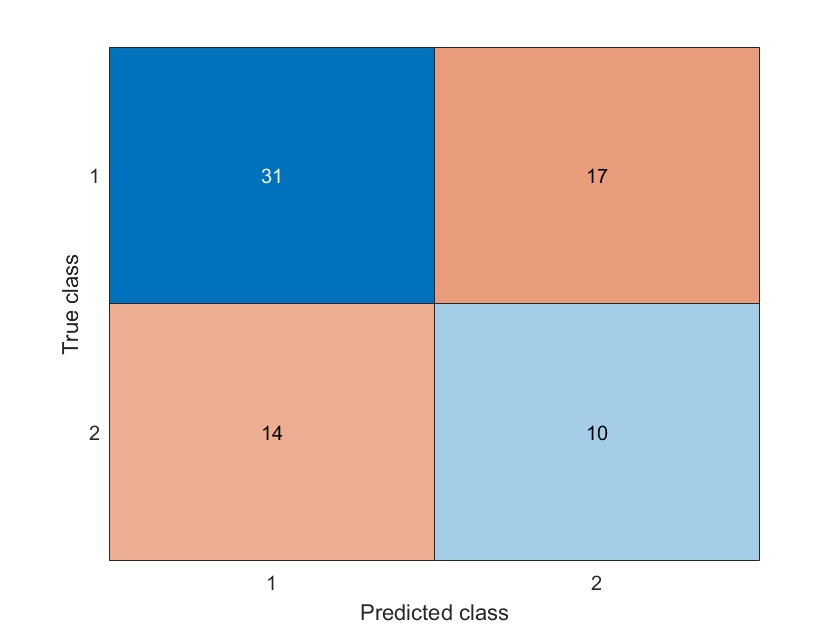

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


for fold=1:folds

**            Find patterns to use for Testing (index==fold) and Training (index!=fold)**

    % Split the dataset in Training and Testing for this fold    
    load("../Dataset/indices_CN-vs-MCIc.mat")
    
    trainingIndices=double([Indices~=fold])';
    trainingIndices=trainingIndices.*[1:length(trainingIndices)];
    trainingIndices=trainingIndices(trainingIndices~=0);
    trainingIndices=double(ismember(labelID,trainingIndices));
    trainingIndices=trainingIndices.*[1:length(trainingIndices)];
    trainingIndices=trainingIndices(trainingIndices~=0);
    
    trainingImages=Images(:,:,:,trainingIndices);
    trainingLabel=label(:,trainingIndices);
    trainingID=labelID(:,trainingIndices);
    
    testingIndices=double([Indices==fold])';
    testingIndices=testingIndices.*[1:length(testingIndices)];
    testingIndices=testingIndices(testingIndices~=0);
    testingIndices=ismember(labelID,testingIndices);
    testingIndices=testingIndices.*[1:length(testingIndices)];
    testingIndices=testingIndices(testingIndices~=0);
    
    testImages=Images(:,:,:,testingIndices);
    testLabel=label(:,testingIndices);
    testID=labelID(:,testingIndices);
    
    clear indices_CN-vs-MCIc.mat trainingIndices testingIndices

   **         Shuffle the trainingImages (and their labels respectively)**

    indicesVector=[1:length(trainingLabel)]; % indices from 1 to trainingImages length (~678)
    indicesVector=indicesVector(randperm(length(indicesVector))); % Shuffle vector of indices
    
    trainingImages=trainingImages(:,:,:,indicesVector);
    trainingLabel=trainingLabel(:,indicesVector);
    trainingID=trainingID(:,indicesVector);

            **Train**

    valueset = [1:2];
    Y=categorical(trainingLabel',valueset);
    
    [trainedNet,info]=trainNetwork(trainingImages,Y,layers,options);

**            Save the trained model**

    save(directory+"trainedModel"+fold+".mat", "trainedNet");
    save(directory+"trainingInfo"+fold+".mat","info");

            **Validation**

    predictions = classify(trainedNet,testImages);

**            Metrics**

    predictions=double(predictions);

    TP(fold)= sum(and((predictions==2)',testLabel==2))
    TN(fold)= sum(and((predictions==1)',testLabel==1))
    FP(fold)= sum(and((predictions==2)',testLabel==1))
    FN(fold)= sum(and((predictions==1)',testLabel==2))
    
    precision(fold)= TP(fold)/(TP(fold)+FP(fold))
    recall(fold)=TP(fold)/(TP(fold)+FN(fold))
    f1(fold)=2*(precision(fold)*recall(fold))/(precision(fold)+recall(fold))
    specificity(fold)=FP(fold)/(FP(fold)+TN(fold))
    accuracy(fold)=(TP(fold)+TN(fold))/(TP(fold)+TN(fold)+FP(fold)+FN(fold))

    confusionchart(testLabel,predictions)
    
    
    
end %End of cross fold validation

### **Save metrics**

save(directory+"Metrics.mat","TP","TN","FP","FN","precision","recall","f1","specificity","accuracy")


function [IMG]=mriToCNN(IMG,siz,axis) 
    % Removing NaN values
    IMG(find(isnan(IMG)))=0;
    
    % Extract 6 slices in sequence from the middle
    % Resize each 121x145 slice to 227x227
    for livello=1:nSlices
        if axis=="x-axis"
            middle=size(IMG);
            middle=floor(middle(1)/2); %index of the middle slice
            slice=middle-floor(nSlices/2)+livello*gap; %Slice to extract index
            IMG=imresize(squeeze(IMG(slice,:,:)),[siz(1) siz(2)]);
        end
        if axis=="y-axis"
            middle=size(IMG);
            middle=floor(middle(2)/2); %index of the middle slice
            slice=middle-floor(nSlices/2)+livello*gap; %Slice to extract index
            IMG=imresize(squeeze(IMG(:,slice,:)),[siz(1) siz(2)]);
            
        end
        if axis=="z-axis"
            middle=size(IMG);
            middle=floor(middle(3)/2); %index of the middle slice
            slice=middle-floor(nSlices/2)+livello*gap; %Slice to extract index
            IMG=imresize(squeeze(IMG(:,:,slice)),[siz(1) siz(2)]);
        end
        RID(:,:,1,livello)=IMG;
        RID(:,:,2,livello)=IMG;
        RID(:,:,3,livello)=IMG;
    end
    
    clear IMG
    
    % Normalize values
    M=max(RID(:));
    IMG=floor(RID.*(255/M));
    
    clear RID
end